# Clasificación con Separadores Lineales 

**Proyecto I : Programación Cuadrática**

**ITAM**

**Optimización Numérica**

Integrantes:

- Luis Felipe Castro Corrales            181417

- Natalia Hernández Cornejo            183420

- Dara Ximena Meneses Acosta       190689

En este proyecto, utilizaremos el método de puntos interiores para obtener un clasificador lineal. Utilizaremos una base de datos que contiene tres tipos de vinos y que los describe con 13 atributos. El objetivo es, para cada vino, encontrar el hiperplano que maximize el margen entre este y los demás.

% Ejecutar esta línea para limpiar el espacio de trabajo.
clear; close all; clc;

### Descripción de los datos

La base de datos es el resultado de análisis químicos que se le hicieron a vinos que fueron cultivados en la misma región de Italia pero que son de tres diferentes variedades. El análisis determina las cantidades para cada tipo de vino de los siguientes 13 componentes:

- Alcohol 

- Acido málico 

- Ceniza 

- Alcanidad de la ceniza   

- Magnesio

- Fenoles totales  

- Flavanoides

- Fenoles no-flavanoides 

- Proantocianidinas 

- Intensidad de color 

- Matiz 

- OD280/OD315 de vinos diluidos

- Prolina

**Importamos los datos de los vinos**

En primer lugar, cargamos la base de datos de vinos y los separamos por tipo.

Vt = readmatrix('wine/wine.data','FileType','text');

V1 = Vt(1:59,2:end);
V2 = Vt(60:130,2:end);
V3 = Vt(131:end,2:end);
clear Vt;

**Visualización**

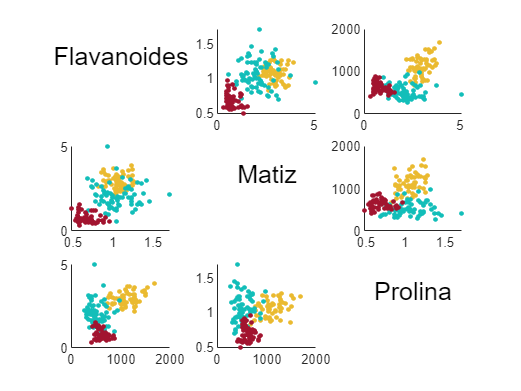

figure;
n = 3;
txtsz = 15;
h1 = subplot(n, n, 1);
text((max(h1.XLim)-min(h1.XLim))/2+min(h1.XLim),(max(h1.YLim)-min(h1.YLim))/2+min(h1.YLim),'Flavanoides','FontSize',txtsz,'HorizontalAlignment', 'center','VerticalAlignment','Bottom');
axis off
h1 = subplot(n, n, n+2);
text((max(h1.XLim)-min(h1.XLim))/2+min(h1.XLim),(max(h1.YLim)-min(h1.YLim))/2+min(h1.YLim),'Matiz','FontSize',txtsz,'HorizontalAlignment', 'center','VerticalAlignment','Bottom');
axis off
h1 = subplot(n, n, 2*n+3);
text((max(h1.XLim)-min(h1.XLim))/2+min(h1.XLim),(max(h1.YLim)-min(h1.YLim))/2+min(h1.YLim),'Prolina','FontSize',txtsz,'HorizontalAlignment', 'center','VerticalAlignment','Bottom');
axis off

nums = [7 11 13];
for i = 1:n
    for j = 1:n
        if (i~=j)
            subplot(n, n, n*(i-1)+j);
            hold on
            scatter(V1(:,nums(i)),V1(:,nums(j)),8, [0.9184  0.7308  0.1890], "filled")
            scatter(V2(:,nums(i)),V2(:,nums(j)),8, [0.0704  0.7457  0.7258], "filled")
            scatter(V3(:,nums(i)),V3(:,nums(j)),8, [0.6350  0.0780  0.1840], "filled")
        end
    end
end

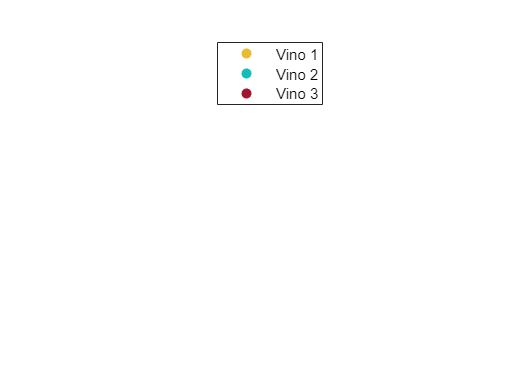


figure
hold on
scatter(NaN,NaN,8,[0.9184  0.7308  0.1890],'filled')
scatter(NaN,NaN,8,[0.0704  0.7457  0.7258],'filled')
scatter(NaN,NaN,8,[0.6350  0.0780  0.1840],'filled')
legend('Vino 1','Vino 2','Vino 3')
legend(Location="north")
axis off

#### Separamos el primer vino del segundo

Usamos la función *separaLineal* (que se encuentra al final del archivo) para obtener el hiperplano que divide el primer vino del segundo. Esta función implementa el programa *qpintpoint2* para resolver el problema cuadrático con restricciones de desigualdad.

Iter     CNPO
  1 20340.88797841 
  2 9567.37188207 
  3 4165.94527016 
  4 1169.93499805 
  5 355.33573562 
  6 184.53150842 
  7 0.92636658 
  8 0.04697040 
  9 0.03450772 
 10 0.01184373 
 11 0.00562959 
 12 0.00280656 
 13 0.00140100 
 14 0.00069998 
 15 0.00034985 
 16 0.00017489 
 17 0.00008744 
 18 0.00004372 
 19 0.00002186 
 20 0.00001093 
 21 0.00000546 


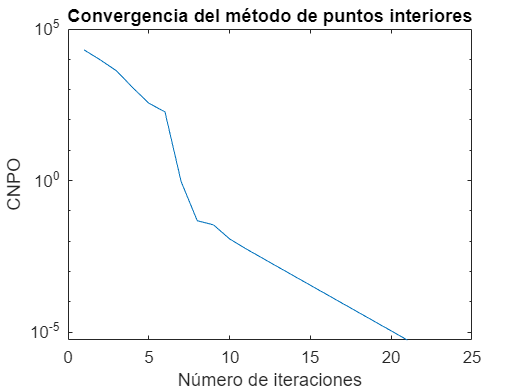

AA = V1;
BB = V2;

[w, beta, ~, ~, ~, tiempo] = separaLineal(AA,BB);

w

w =    -1.0915
   -0.5914
   -2.0557
    0.2027
   -0.0027
    0.2413
   -0.4505
   -0.4826
    0.0183
   -0.3588


beta

beta = 23.2419

norma_w = norm(w)

norma_w = 2.5806

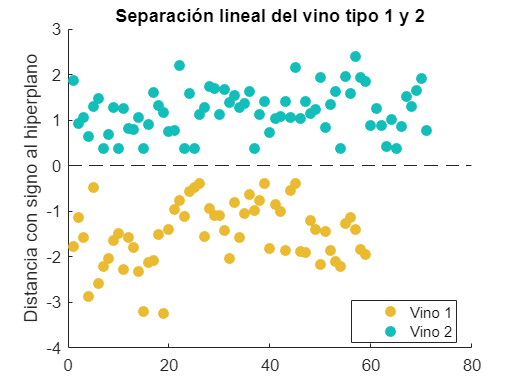


S1 = (AA*w + beta)/norma_w;
S2 = (BB*w + beta)/norma_w;

figure;
hold on
h = stem(S1,'filled','LineStyle','none','color',[0.9184    0.7308    0.1890]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S2,'filled','LineStyle','none','color',[0.0704    0.7457    0.7258])
legend('Vino 1','Vino 2','Location','best')
title('Separación lineal del vino tipo 1 y 2')
ylabel('Distancia con signo al hiperplano')

tiempo

tiempo = 0.6875

#### Separamos el primer vino del tercero

Iter     CNPO
  1 17329.29851572 
  2 3673.72769984 
  3 1607.90414308 
  4 447.48777103 
  5 219.35167099 
  6 7.47070531 
  7 1.12658292 
  8 0.04586746 
  9 0.02354463 
 10 0.01191625 
 11 0.00593407 
 12 0.00307472 
 13 0.00164326 
 14 0.00072993 
 15 0.00032113 
 16 0.00015930 
 17 0.00007948 
 18 0.00003970 
 19 0.00001984 
 20 0.00000992 


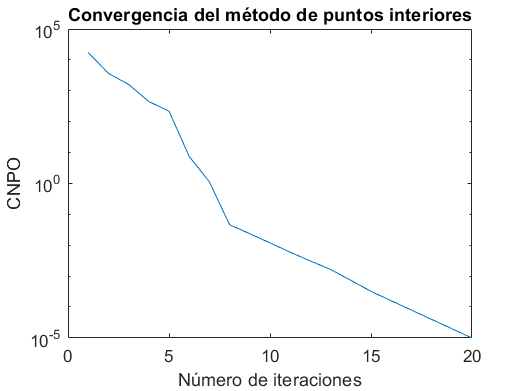

AA = V1;
BB = V3;

[w, beta, ~, ~, ~, tiempo] = separaLineal(AA,BB);

w

w =    -0.0702
   -0.1039
   -0.0785
    0.0770
   -0.0114
   -0.3196
   -0.4962
   -0.0053
   -0.1826
    0.1166


beta

beta = 4.6624

norma_w = norm(w)

norma_w = 0.7526

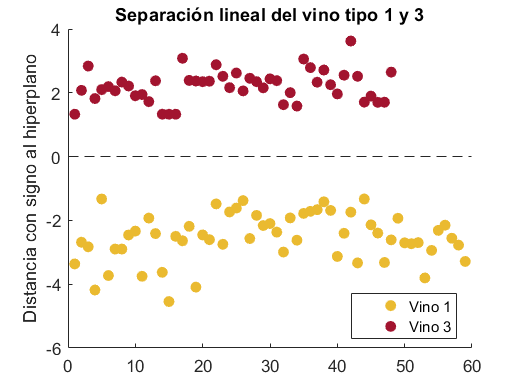


S1 = (AA*w + beta)/norma_w;
S3 = (BB*w + beta)/norma_w;

figure;
hold on
h = stem(S1,'filled','LineStyle','none','color',[0.9184    0.7308    0.1890]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S3,'filled','LineStyle','none','color',[0.6350     0.0780      0.1840])
legend('Vino 1','Vino 3','Location','best')
title('Separación lineal del vino tipo 1 y 3')
ylabel('Distancia con signo al hiperplano')

tiempo

tiempo = 0.3281

#### Separamos el segundo vino del tercero

Iter     CNPO
  1 6189.50540123 
  2 4455.07482602 
  3 3414.83872127 
  4 2048.17323298 
  5 1222.73709083 
  6 772.25528706 
  7 553.66508792 
  8 310.40850954 
  9 184.37334824 
 10 96.61181515 
 11 48.38009447 
 12 43.00475991 
 13 39.98725936 
 14 18.47079302 
 15 6.98500266 
 16 4.40643483 
 17 0.44165071 
 18 0.00220943 
 19 0.00002561 
 20 0.00001068 
 21 0.00000524 


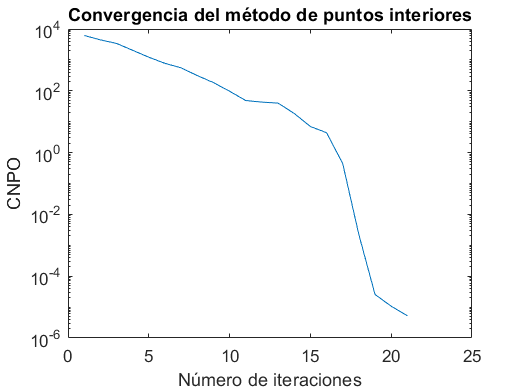

AA = V2;
BB = V3;

[w, beta, ~, ~, ~, tiempo] = separaLineal(AA,BB);

w

w =     0.9814
    0.3515
    1.1830
   -0.0729
    0.0572
   -0.0548
   -2.1242
   -0.2888
    0.2345
    0.9882


beta

beta = -22.5069

norma_w = norm(w)

norma_w = 3.2381

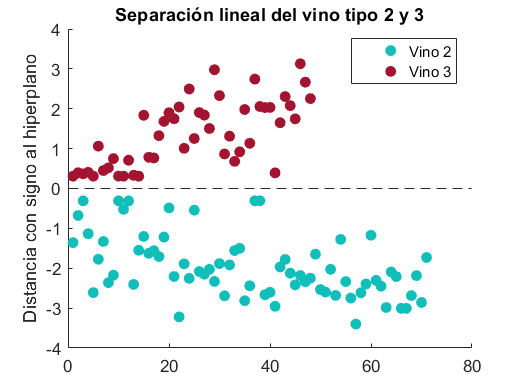


S2 = (AA*w + beta)/norma_w;
S3 = (BB*w + beta)/norma_w;

figure;
hold on
h = stem(S2,'filled','LineStyle','none','color',[0.0704    0.7457    0.7258]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S3,'filled','LineStyle','none','color',[0.6350 0.0780 0.1840])
legend('Vino 2','Vino 3','Location','best')
title('Separación lineal del vino tipo 2 y 3')
ylabel('Distancia con signo al hiperplano')

tiempo

tiempo = 0.5000

### Clasificador lineal para dos conjuntos A y B por el método de puntos interiores.

Trataremos de encontrar el cero de la función G que describe las condiciones necesarias de primer órden.

function [w, beta, mu, z, iter, tiempo] = separaLineal(A,B)
    [m, n] = size(A);
    [k, ~] = size(B);

    Q = [  eye(n)    zeros(n,1);
         zeros(1,n)     0
        ];
    c = zeros(n+1,1);

    F = [-A -ones(m,1);
          B  ones(k,1)
        ];
    d = ones(m+k,1);

    % Obtenemos el separador por método del punto interior
 
    inicio=cputime;
    [x, mu, z, iter] = qpintpoint2(Q,F,c,d);
    fin=cputime;
    tiempo=fin-inicio;
    w = x(1:n);
    beta = x(n+1:end);
end